# Lab 1 Exercises 

## 1. Setup 

    1.1 Start Matlab 

    1.2 Download and install Peter Corke’s modified robotics toolbox (See UTSOnline) 

    1.3 Run the demos (type “rtbdemo”) to show the arms and get an idea what is possible.

## 2. Consider a car driving around a circular track

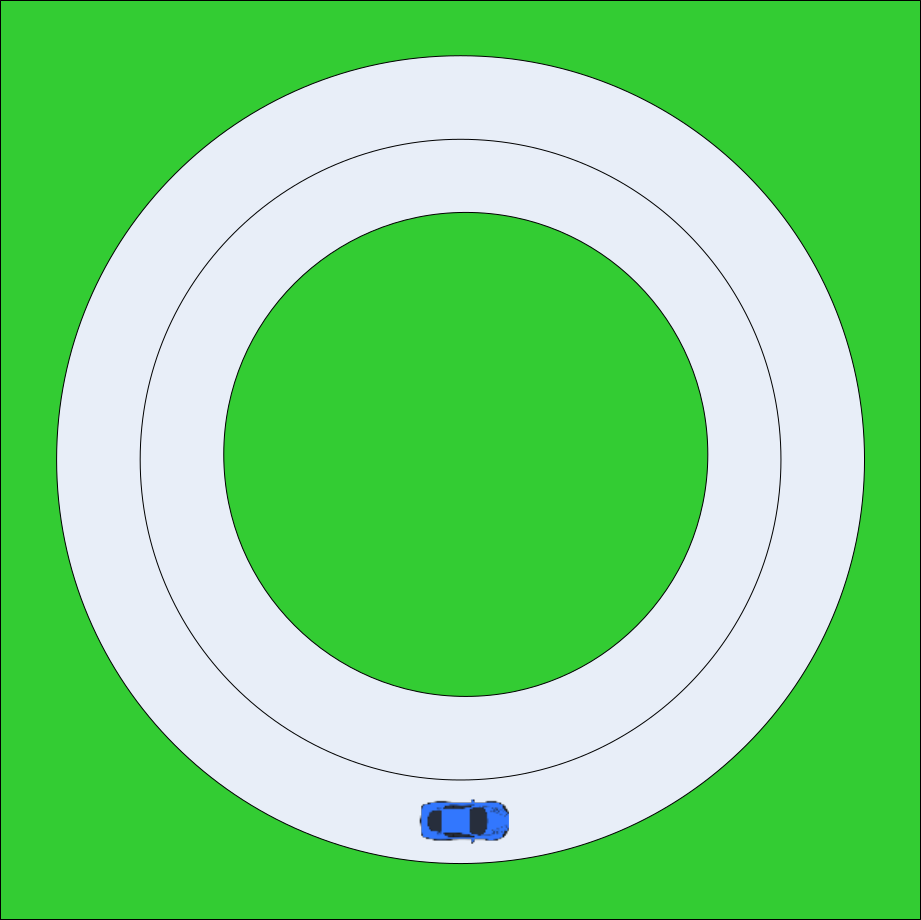

    2.1 Download the image from UTSOnline to file “W1LabEx1_CircularRaceTrack.jpg”, then open Matlab and Load the image with: 

t = tiledlayout(2,1);
ax1 = nexttile(1,[1,1]);
imshow('Lab1_CircularRaceTrack.jpg'); 
axis on;
centre_x = 313;
centre_y = 313;
rotation_speed = 0.01;
x = zeros(0);
y = zeros(0);

    2.2 Plot a transform representing the car at [300,550], use the ‘X’ axis of the transform to represent the heading of the car (note you will need to use “hold on” to show both)

T_car_red = se2(300,550,0);
hold on
h_T_car_red = trplot2(T_car_red,'frame', 'car_red', 'color', 'r', 'length', 50);

    2.3 Make the leg lengths of the transform 50 units long so it is visible on the track.

%car_h = trplot2(car_T, 'frame', 'car_frame', 'color', 'b', 'length', 50);

    2.4 Now incrementally multiply the transform of the car by an offset transform and update the transform of the car

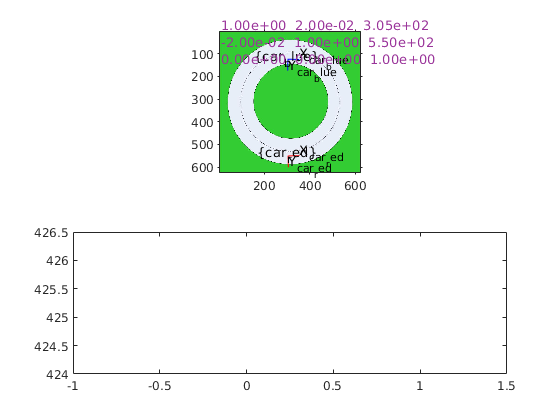

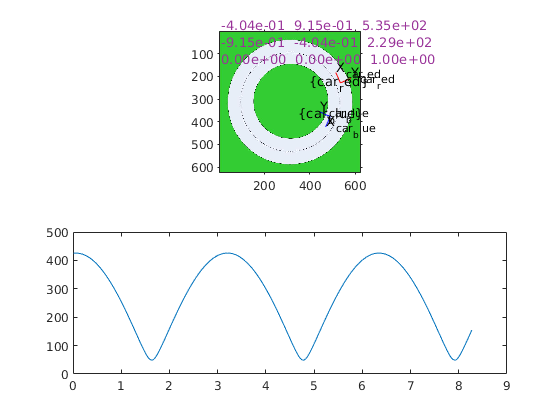

T_car_blue = se2(300, 125, 0);
h_T_car_blue = trplot2(T_car_blue, 'frame', 'car_blue', 'color', 'b', 'length', 50);

T_rotation_red = se2(centre_x,centre_y)* se2(0,0,-rotation_speed)*se2(-centre_x,-centre_y,0);
T_rotation_blue = se2(centre_x,centre_y)* se2(0,0,rotation_speed)*se2(-centre_x,-centre_y,0);

message = sprintf('%0.2e  %0.2e  %0.2e\n%0.2e  %0.2e  %0.2e\n%0.2e  %0.2e  %0.2e',T_car_red(1,1),T_car_red(1,2),T_car_red(1,3),T_car_red(2,1),T_car_red(2,2),T_car_red(2,3),T_car_red(3,1),T_car_red(3,2),T_car_red(3,3));

i = 0;
while i < 1000
    nexttile(1,[1,1]);
    T_car_red = T_rotation_red*T_car_red;
    T_car_blue = T_rotation_blue*T_car_blue;
    
    delete(h_T_car_red);
    delete(h_T_car_blue);
    h_T_car_red = trplot2(T_car_red, 'frame', 'car_red', 'color', 'r', 'length', 50);
    h_T_car_blue = trplot2(T_car_blue, 'frame', 'car_blue', 'color', 'b', 'length', 50);

    message = sprintf('%0.2e  %0.2e  %0.2e\n%0.2e  %0.2e  %0.2e\n%0.2e  %0.2e  %0.2e',T_car_red(1,1),T_car_red(1,2),T_car_red(1,3),T_car_red(2,1),T_car_red(2,2),T_car_red(2,3),T_car_red(3,1),T_car_red(3,2),T_car_red(3,3));
    delete(tf_text);
    tf_text= text(10, 50, message, 'FontSize', 10, 'Color', [.6 .2 .6]);
    drawnow();
    pause(0.01);
    i= i+1;
    T_red_to_blue = inv(T_car_red) * T_car_blue;
    distance = sqrt(T_red_to_blue(1,3)^2 + T_red_to_blue(2,3)^2);
    x = [x, i*0.01];
    y = [y, distance];
    nexttile(2,[1,1]);
    plot(x,y)
end

    2.5 Display the transform of the car using the Matlab “text” command e.g. 

    message = sprintf('%0.2e  %0.2e  %0.2e\n%0.2e  %0.2e  %0.2e\n%0.2e  %0.2e  %0.2e',T_centre(1,1),T_centre(1,2),T_centre(1,3),T_centre(2,1),T_centre(2,2),T_centre(2,3),T_centre(3,1),T_centre(3,2),T_centre(3,3))
    delete(tf_text);
    tf_text = text(10, 50, message, 'FontSize', 10, 'Color', [.6 .2 .6]);
    
    
%end

## 3. Consider a second car driving in the opposite direction

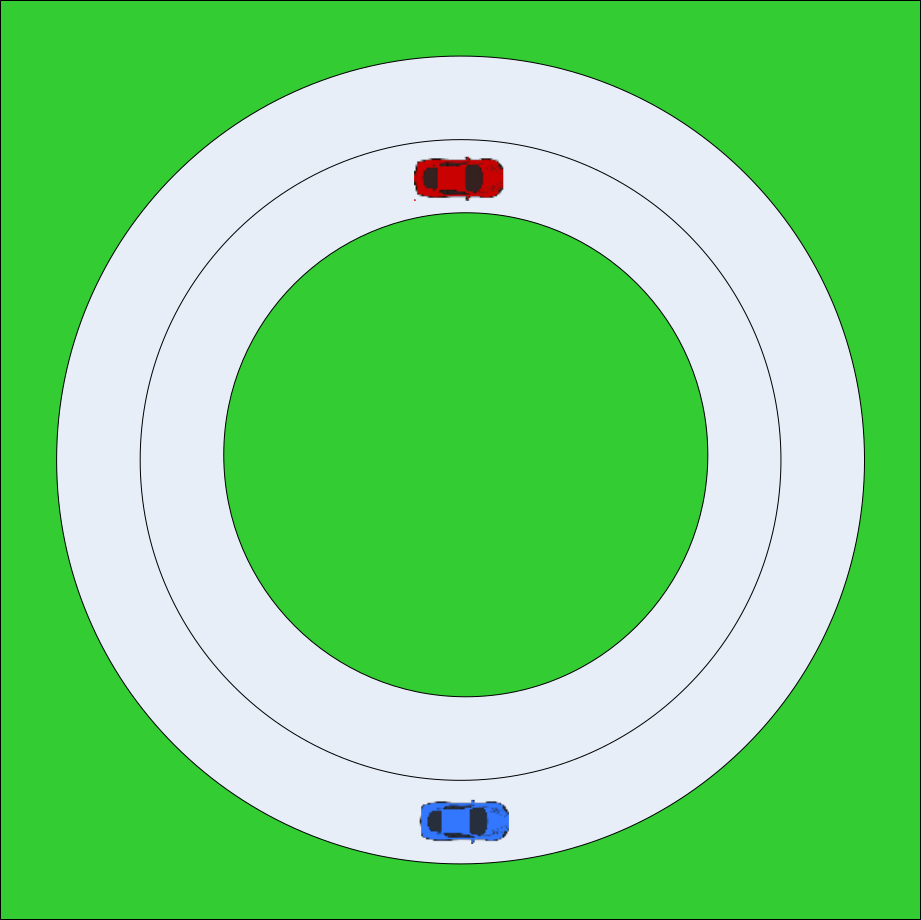

    3.1 Plot a transform representing the second car at [300,125], use the ‘X’ axis of the transform to represent the heading of the car, make transform red with length of 50. 

    3.2 Make the second car incrementally drives in the opposite direction to the first car 

    3.3 Determine the relative transform between the two cars at each time step 

## 4. Bonus: Consider a distance sensor mounted to the first car (blue) that is tracking the distance to the second car 

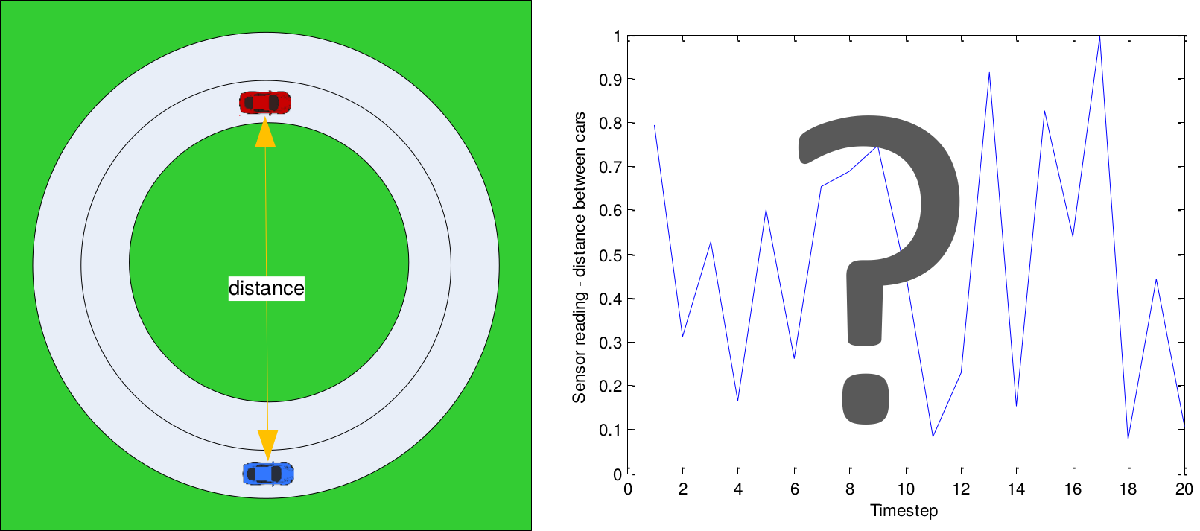

    4.1 Plot a graph of the distances between the two cars as they drive around the track